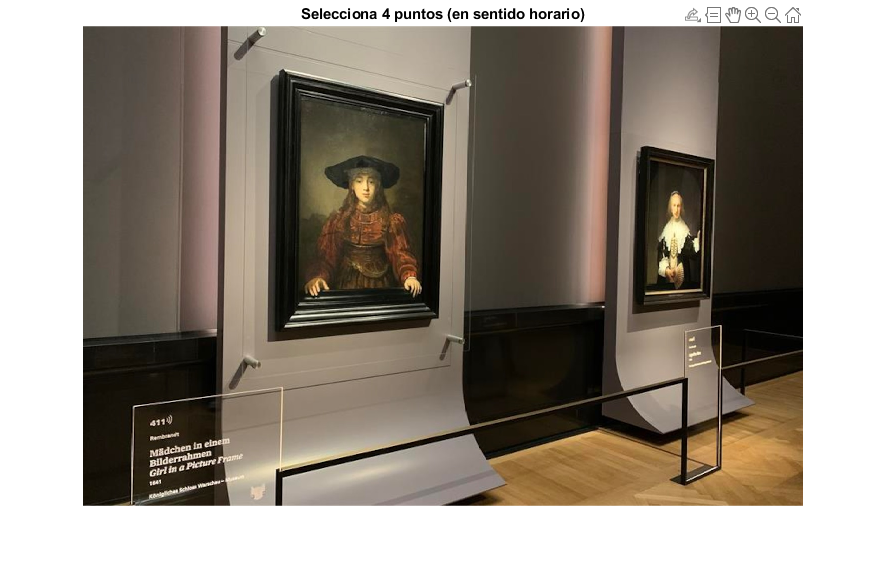

% Leer imagen
img = imread('rembrandt.jpg'); % Usa tu imagen aquí
imshow(img);
title('Selecciona 4 puntos (en sentido horario)');

% Seleccionar 4 puntos
[src_x, src_y] = ginput(4);

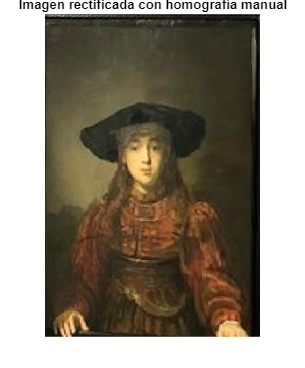

src_pts = [src_x, src_y];

% Definir el destino (rectángulo plano deseado)
width = 400; height = 600;
dst_pts = [0 0; width-1 0; width-1 height-1; 0 height-1];

% Calcular H manualmente
H = calcularHomografia(src_pts, dst_pts); % Usa función definida más abajo

% Crear imagen destino y aplicar homografía manualmente
warped = zeros(height, width, size(img,3), 'uint8');

for y = 1:height
    for x = 1:width
        p_dst = [x; y; 1];
        p_src = inv(H) * p_dst;
        p_src = p_src / p_src(3);
        u = p_src(1); v = p_src(2);
        
        if u >= 1 && u <= size(img,2) && v >= 1 && v <= size(img,1)
            warped(y,x,:) = img(round(v), round(u), :);  % vecino más cercano
        end
    end
end

% Mostrar resultado
figure;
imshow(warped);
title('Imagen rectificada con homografía manual');

function H = calcularHomografia(src_pts, dst_pts)
    % src_pts y dst_pts deben ser 4x2 matrices: [x y] por fila
    A = [];
    for i = 1:4
        x = src_pts(i,1);
        y = src_pts(i,2);
        x_p = dst_pts(i,1);
        y_p = dst_pts(i,2);
        
        A = [A;
             -x, -y, -1,  0,  0,  0, x*x_p, y*x_p, x_p;
              0,  0,  0, -x, -y, -1, x*y_p, y*y_p, y_p];
    end

    % SVD
    [~, ~, V] = svd(A);
    
    % Última columna de V es la solución
    h = V(:, end);
    
    % Reshape en matriz 3x3
    H = reshape(h, [3, 3])';
end
